# Быстрое преобразование Фурье в MATLAB

Импортируйте аудиофайл колебания гитарной струны *A220.mp3* в рабочее пространство. Сохраните отсчёты аудиофайла в вектор х, а частотоу дискретизации - в переменную fs.  

Прослушайте аудио.

Обрежьте вектор х до 2^15 отсчётов.

Выполните быстрое проеобразование Фурье, результат преобразования сохраните в переменную X.

Отобразите модуль вектора Х функцией *area*:

Подписи для графика:

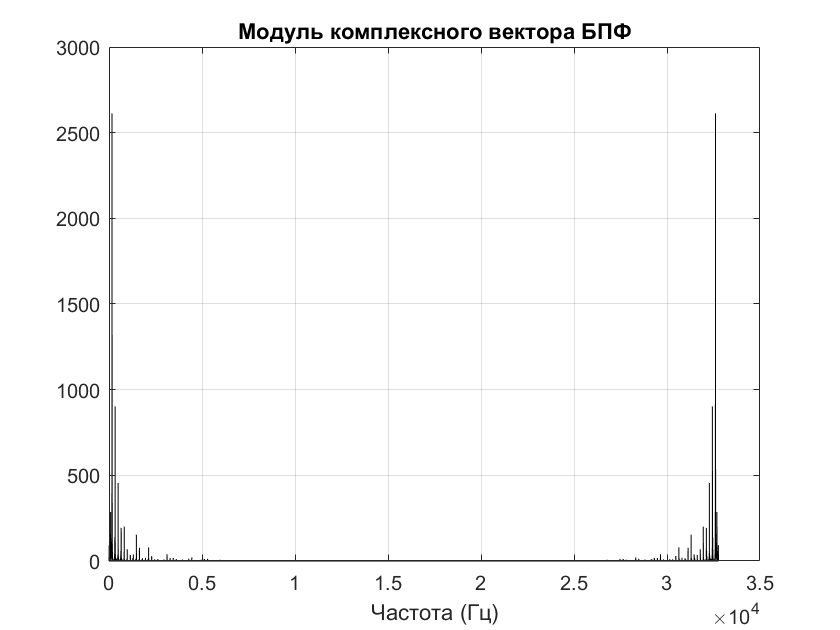

title('Модуль комплексного вектора БПФ');
xlabel('Частота (Гц)');
grid on;

Функция ***fftshift*** преобразует спектр (выход функции ***fft***) и сдвигает отсчёты симметрично относительно нулевой частоты. Передайте ей на вход комплексный вектор *Х*, и сохраните результат в переменную *Xshift*.

Создайте вектор частот *F* в пределах от минус половины частоты дискретизации до половины частоты дискретизации (*fs/2*). Кол-во отсчётов в векторе должно совпадать с кол-вом отсчётов вектора *Х*.

Отобразите зависимость амплитудного спектра сигнала от частоты с помощью функции *area* в пределах от -2000 Гц до 2000 Гц (подсказка: воспльзуйтесь функцией *xlim*).

Подписи для графика:

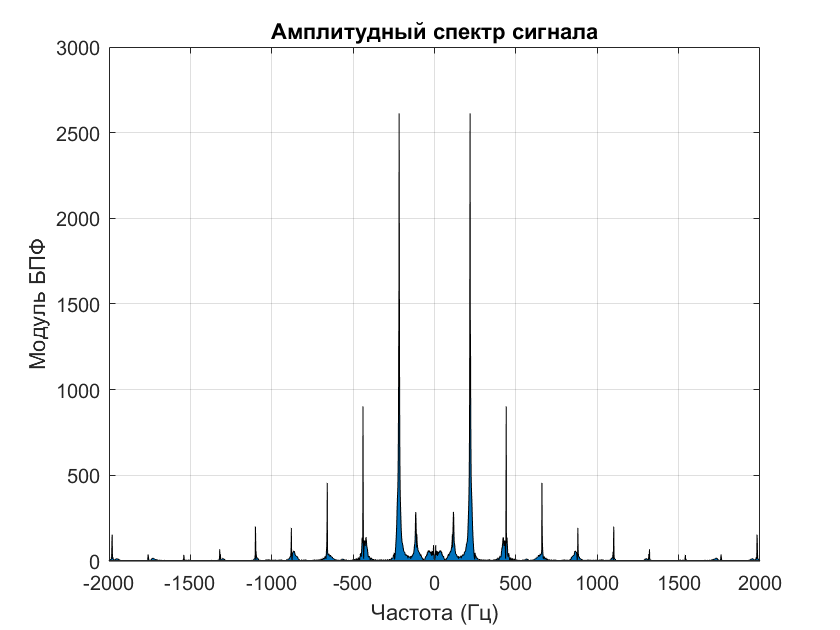

title('Амплитудный спектр сигнала');
xlabel('Частота (Гц)');
ylabel('Модуль БПФ');
grid on; 

Сохраните в отдельную переменную значения вектора Х, соответствующие положительной области частот. Для этого выделите только первую половину отсчётов вектора Х, и сохраните в переменную *Xpositive*.

Также создайте вектор частот для положительной области *Fpositive*. Он должен охватывать пределы от 0 Гц до половины частоты дискретизации, а также иметь столько же отсчётов, сколько и вектор *Xpositive*.

Отобразите зависимость амплитудного спектра сигнала от частоты с помощью функции *area* в пределах от 0 Гц до 1500 Гц.

Подписи для графика:

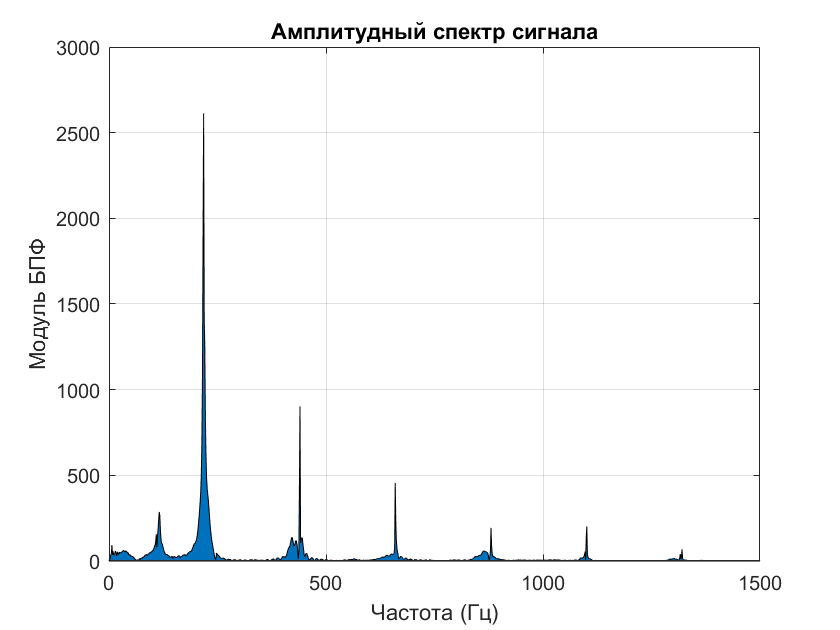

title('Амплитудный спектр сигнала');
xlabel('Частота (Гц)');
ylabel('Модуль БПФ');
grid on;
hold on;

Нам интересно увидеть гармоническую структуру на спектре колебания струны. Для этого мы попроуем найти локальные максимумы, соответствующие наиболее выделяющимся колебаниям.

Воспользуйтесь функцией *findpeaks. *Передайте ей в качестве входного вектора модуль переменной *Xpositive*, а также укажите параметры минимальной высоты пиков не менее 100, и минимального расстояния между пиками также не менее 100. Не сохраняйте значения максимумов, но сохраните индексы соответствующих им отсчётов в переменную *locs* (подсказка: у функции *findpeaks* не должно быть первого выхода).

Определите частоты, на которых находятся локальные максимумы. Сохраните эти частоты в вектор *Fpeaks*.

Отобразите локальные максимумы красными треугольными маркерами на графике амлитудного спектра.

Подписи текста на графике:

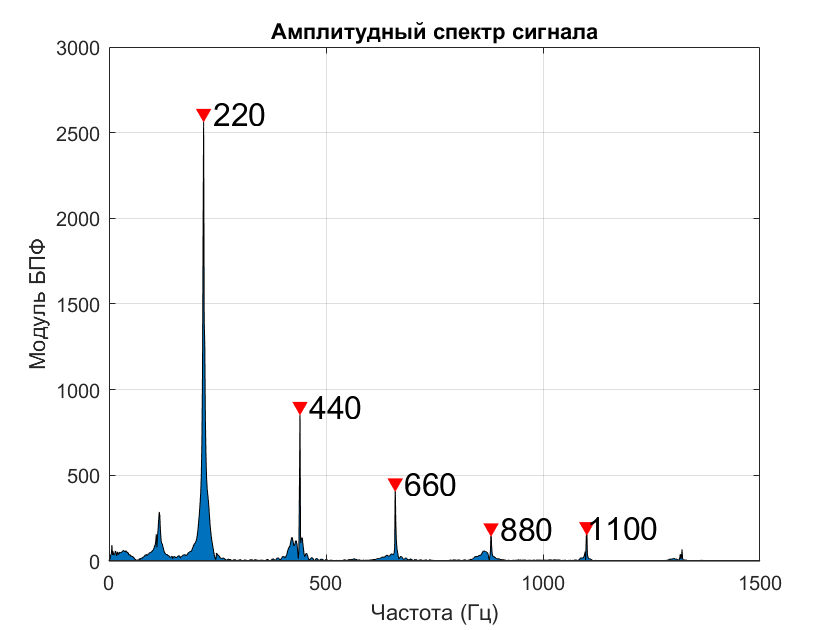

cellpeaks = cellstr(num2str(round(Fpeaks',-1)));
text(Fpeaks,abs(Xpositive(locs)),cellpeaks,'FontSize',16);
hold off;

Проверьте, соответвтуют ли значения частот локальных максимумов гармоникам основного колебания - ноты Ля малой октавы. Основные частоты нот: